# Running a Constrained Optimisation with SNOBFit

**Barnaby Walker, James H. Bannock, Adrian M. Nightingale, and John C. de Mello**

In our article, 'Tuning Reaction Products by Constrainted Optimsation', we use the algorithm '**Stable Noisy Optimisation by Branch and Fit (SNOBFit)**' by Huyer and Neumaier to carry out chemical optimisations. For convenience, we have developed a class-based wrapper for their [Matlab-based implementation of SNOBFit](http://www.mat.univie.ac.at/neum/software/snobfit/) ([http://www.mat.univie.ac.at/neum/software/snobfit/](http://www.mat.univie.ac.at/neum/software/snobfit/)), which simplifies both the installation of SNOBFit and its use, especially for chemical and blackbox optimisations.. The following tutorial explains how to use this package to run a **constrained optimisation.**

This tutorial follows on from the introductory tutorial '**using_snobfit.mlx'** in the '**tutorials**' folder. You are advised to begin with that one before reading this.

## RUNNING A CONSTRAINED OPTIMISATION

Install the SNOBFit package by following the instructions in the preceding tutorial. As before the package must be imported before use by typing:

import snobfitclass.*

(Make sure that you are in the same folder as the package or that you have added the folder containing the package to the Matlab path).

## Creating the SNOBFit Object

As before, you must first create a SNOBFit object. You can create the object and populate its name property in a single step by typing:

snobfit_object = snobfitclass.snobclass('name', 'my_first_constrained_snobfit')

User must enter function and setup values!


snobfit_object =   snobclass with properties:

             name: 'my_first_constrained_snobfit'
              fcn: 'none'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: []
        minimised: []
            fbest: []
            xbest: []
            ncall: 100
      termination: 'n_runs'


## Setting Up a Constrained Optimisation

You must also specify the name of the objective function to minimise. In this example we will be using a test function defined by the equation:


$$f\left(x_1 ,x_2 \right)=0\ldotp 01x_1^2 +x_2^2 \ldotp$$


You will find  a pre-coded version of this function in the '**+objfcn' **folder in the file entitled '**hsf18.m.'**

snobfit_object.fcn = 'hsf18'

SNOBFIT experiment has been created!


snobfit_object =   snobclass with properties:

             name: 'my_first_constrained_snobfit'
              fcn: 'hsf18'
    constraintFcn: 'none'
           linked: 0
      constrained: 1
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 10000
      termination: 'n_runs'


For a constrained optimisation you must also provide the name of the file containing the constraint definitions. Here we will use the file '**hsf18.m**' in the '**+confcn**' folder, which contains the following constraints:


$$\begin{array}{l}
F_1 \left(x_1 ,x_2 \right):\text{ }{0<\text{ }x}_1 x_2 -25\\
F_2 \left(x_1 ,x_2 \right):\text{ }0<{x_1 }^2 +{x_2 }^2 -25
\end{array}$$


[CHANGE ILLUSTRATION TO HAVE TERMINATION AS nCall]

snobfit_object.constraintFcn = 'hsf18'

snobfit_object =   snobclass with properties:

             name: 'my_first_constrained_snobfit'
              fcn: 'hsf18'
    constraintFcn: 'hsf18'
           linked: 0
      constrained: 1
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 10000
      termination: 'n_runs'


Note, although in this example the objective and constraint functions have the same name, they are different files saved in separate folders. For information about how to define your own objective and constraint functions, please refer to the separate tutorial '**defining_an_optimisation.md**'.

 For a constrained optimisation, it is necessary to set the preferred bounds of the constraints:

snobfit_object.F_lower = [0, 0]';      % the lower bound:  the first element refers to the first constrained property; the second element refers to the second constrained property.
snobfit_object.F_upper = [Inf, Inf]';  % the upper bounds: the first element refers to the first constrained property; the second element refers to the second constrained property.

You must also set sigma values that define the extent to which the bounds may be violated:

snobfit_object.sigma = [1.25, 1.25]';

As with an unconstrained optimisation, there are several other settings that can be adjusted, such as the maximum number of function calls and the termination crierion:

snobfit_object.ncall = 100;
snobfit_object.termination = 'n_runs';

At this point, you may run a constrained SNOBFit optimisation by typing:

SNOBFIT experiment is running...
ncall:	1 to 6
xbest:	41.088000, 4.900000
fbest:	0.071684
ncall:	7 to 12
xbest:	21.408000, 5.400000
fbest:	0.058592
ncall:	13 to 18
xbest:	28.464000, 2.600000
fbest:	0.022172
ncall:	19 to 24
xbest:	28.464000, 2.600000
fbest:	0.022172
ncall:	25 to 30
xbest:	28.464000, 2.600000
fbest:	0.022172
ncall:	31 to 36
xbest:	28.464000, 2.600000
fbest:	0.022172
ncall:	37 to 42
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	43 to 48
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	49 to 54
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	55 to 60
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	61 to 66
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	67 to 72
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	73 to 78
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	79 to 84
xbest:	32.112000, 1.600000
fbest:	0.018169
ncall:	85 to 90
xbest:	21.360000, 1.500000
fbest:	0.005775
ncall:	91 to 96
xbest:	21.360000, 1.500000
fbest:	0.005775
ncall:	97 to 102
xbest:	21

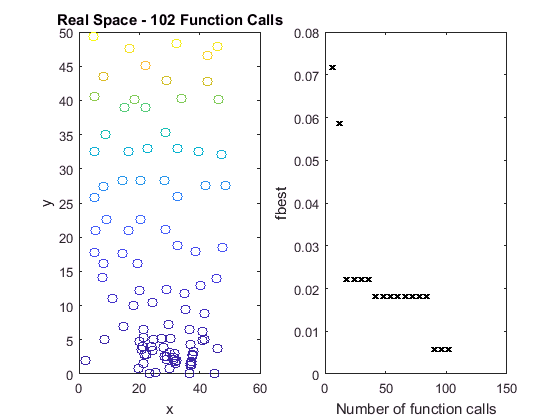

snobfit_object.startExp;

As the optimisation proceeds, the SNOBFit object prints out the latest input parameters and the current best function value. It also plots a scatter graph of all the points tested so far, together with a plot of the best function value versus the number of function calls.

## ACCESSING YOUR RESULTS

After your optimisation has completed, you can extract the results from the SNOBFit object.

To extract the best function value, you should type:

snobfit_object.fbest

ans = 0.0058

And to see the location of the best point:

snobfit_object.xbest

ans =    21.3600    1.5000


You can also access the location of the best fully feasible point, i.e. the best point  that satisfied the preferred constraints:

snobfit_object.xcon

ans =    21.3600    1.5000


And the corresponding value of of the constrained merit function:

snobfit_object.fcon

ans = 6.8125

You can also see all of the parameters that SNOBFit tested:

snobfit_object.x

ans =     2.0160    2.0000
   41.0880    4.9000
   45.4560   13.9000
    8.1120   27.3500
   45.8400   47.9000
   32.3520   48.2500
    4.8480   49.4000
   28.2720   28.2500
   21.4080    5.4000
   47.0880   32.0500


And all of the objective function values that these gave:

snobfit_object.f

ans =    1.0e+03 *

    0.0040
    0.0409
    0.2139
    0.7487
    2.3154
    2.3385
    2.4406
    0.8061
    0.0337
    1.0494


All of the constraint function values:

snobfit_object.F

ans =    1.0e+03 *

   -0.0210   -0.0169
    0.1763    1.6872
    0.6068    2.2345
    0.1969    0.7888
    2.1707    4.3707
    1.5360    3.3497
    0.2145    2.4389
    0.7737    1.5724
    0.0906    0.4625
    1.4842    3.2195


And all of the constrained merit values:

snobfit_object.fm

ans =     1.9957
    0.0717
    0.3054
    0.6094
    0.8289
    0.8303
    0.8362
    0.6269
    0.0586
    0.6866


As before, you can plot the data in your preferred format, e.g.

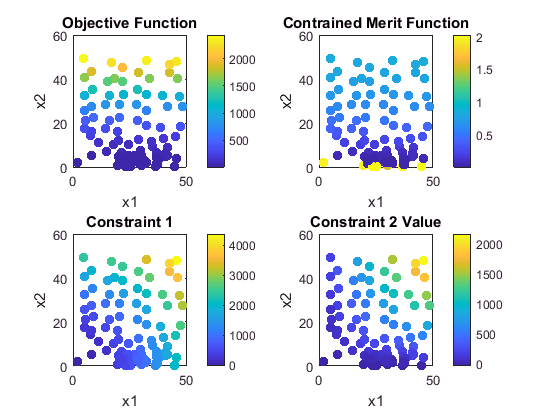

figure
subplot(221)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.f, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Objective Function')

subplot(222)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.fm, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Contrained Merit Function')

subplot(223)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.F(:,2), 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Constraint 1')

subplot(224)
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.F(:,1), 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Constraint 2 Value')

As well as storing your results inside the SNOBFit object itself, the object also saves a copy of itself in a '.mat' file, and the results and a summary of the optimisation in comma-separated (.csv) files in the Results folder on the object's filepath. This means that you can load the SNOBFit object back into MATLAB from the .mat file to access the results or continue the optimisation, even if your computer turns off without you manually saving anything.